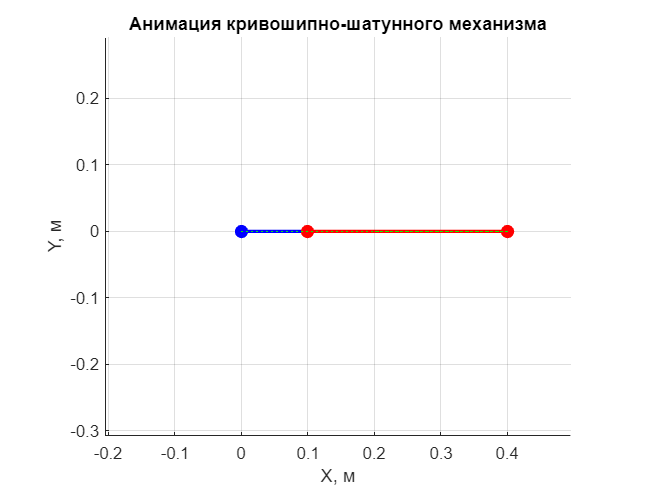

% Параметры механизма
r = 0.1; % Длина кривошипа OA
l = 0.3; % Длина шатуна AB
h = 0.2; % Расстояние OC (положение точки C)

% Создание массива углов поворота кривошипа
phi1 = linspace(0, 2*pi, 100); % 100 точек на полный оборот

% Функция расчета координат (должна быть в отдельном файле calculate_coordinates.m)
% function [x_A, y_A, x_B, y_B, x_C, y_C] = calculate_coordinates(phi, r, l, h)
%     x_A = r * cos(phi);
%     y_A = r * sin(phi);
%     
%     % Расчет координат точки B (ползун)
%     sin_phi2 = (r/l) * sin(phi);
%     cos_phi2 = sqrt(1 - sin_phi2^2);
%     x_B = r * cos(phi) + l * cos_phi2;
%     y_B = 0; % Ползун движется по горизонтальной линии
%     
%     % Координаты точки C (неподвижная опора)
%     x_C = h;
%     y_C = 0;
% end

% Подготовка фигуры для анимации
h_fig = figure('Name', 'Анимация движения КШМ', 'Position', [200, 200, 800, 600]);
hold on; grid on; axis equal;
xlim([-0.2, 0.5]); ylim([-0.3, 0.3]); % Подберите пределы под ваши параметры
xlabel('X, м'); ylabel('Y, м');
title('Анимация кривошипно-шатунного механизма');

% Инициализация графических объектов
h_rod1 = plot(0, 0, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
h_rod2 = plot(0, 0, 'r-o', 'LineWidth', 2, 'MarkerFaceColor', 'r');
trajectory = plot(0, 0, 'g:', 'LineWidth', 0.5); % Для траектории точки B

% Цикл анимации
for i = 1:length(phi1)
    % Расчет координат для текущего положения
    phi = phi1(i);
    
    % Прямой расчет координат (вместо вызова функции)
    x_A = r * cos(phi);
    y_A = r * sin(phi);
    
    % Расчет координат точки B (ползун)
    sin_phi2 = (r/l) * sin(phi);
    cos_phi2 = sqrt(1 - sin_phi2^2);
    x_B = r * cos(phi) + l * cos_phi2;
    y_B = 0; % Ползун движется по горизонтальной линии
    
    % Координаты точки C (неподвижная опора)
    x_C = h;
    y_C = 0;

    % Обновление данных графических объектов
    set(h_rod1, 'XData', [0, x_A], 'YData', [0, y_A]);
    set(h_rod2, 'XData', [x_A, x_B], 'YData', [y_A, y_B]);
    
    % Добавление точки к траектории
    currentX = get(trajectory, 'XData');
    currentY = get(trajectory, 'YData');
    set(trajectory, 'XData', [currentX, x_B], 'YData', [currentY, y_B]);
    
    % Обновление рисунка
    drawnow;
    
    % Пауза для управления скоростью анимации
    pause(0.05);
end